# ABC - DQ Validation

% simwoWT = out; %sim("Version4\version4_ABC.slx", "StopTime", "25");
save("Version4\nonlineartest\simwoWT.mat","simwoWT",'-mat')
% load("Version4\validation\simABCvoltsag.mat")
% simwWT = out;%sim("Version4\version4_dq.slx","StopTime", "25");
save("Version4\nonlineartest\simwWT.mat","simwWT",'-mat')
% load("Version4\validation\simDQvoltsag.mat")

## woWT values

struc_v_vsc_dq_wo= simwoWT.vi_dq_vsc_big;
struc_vgrid_DQ_wo = simwoWT.V_grid_DQ;

struc_powers_wo = simwoWT.PQ_grid_wdc_big;
struc_vsm_wo = simwoWT.VSM_wdc_big;
struc_dc_link_wo = simwoWT.DC_link_big;
struc_qdroop_wo = simwoWT.Qdroop_wdc_big;
% struc_wt_wo = simwoWT.wind_turbine_big;


## extract data to arrays

t_dc_link_big_wo = struc_dc_link_wo.time;
DC_voltage_big_wo = struc_dc_link_wo.signals(1).values;
DC_power_link_big_wo = struc_dc_link_wo.signals(2).values(:,1);
DC_power_grid_big_wo = struc_dc_link_wo.signals(2).values(:,2);

% v_d_t_vec_big = struc_v_t_dq.signals(2).values(:,1);
% v_q_t_vec_big = struc_v_t_dq.signals(2).values(:,2);
v_d_vsc_vec_big_wo = struc_v_vsc_dq_wo.signals(1).values(:,1);
v_q_vsc_vec_big_wo = struc_v_vsc_dq_wo.signals(1).values(:,2);
P_vsc_big_wo = struc_powers_wo.signals(1).values;
Q_vsc_big_wo = struc_powers_wo.signals(2).values;

VSM_P_Delta_big_wo = struc_vsm_wo.signals(1).values;
VSM_freq_big_wo = struc_vsm_wo.signals(2).values;
VSM_theta_deg_big_wo = struc_vsm_wo.signals(3).values;

% w_wt_big_wo = struc_wt_wo.signals(3).values;


## DQ values

% big signal 
% struc_v_t_dq= simDQ.v_t_wdc_big;
struc_v_vsc_dq= simwWT.vi_dq_vsc_big;
struc_vgrid_DQ = simwWT.V_grid_DQ;

struc_powers = simwWT.PQ_grid_wdc_big;
struc_vsm = simwWT.VSM_wdc_big;
struc_dc_link = simwWT.DC_link_big;
struc_qdroop = simwWT.Qdroop_wdc_big;
struc_wt = simwWT.wind_turbine_big;


## extract data to arrays

t_dc_link_big = struc_dc_link.time;
DC_voltage_big = struc_dc_link.signals(1).values;
DC_power_link_big = struc_dc_link.signals(2).values(:,1);
DC_power_grid_big = struc_dc_link.signals(2).values(:,2);

% v_d_t_vec_big = struc_v_t_dq.signals(2).values(:,1);
% v_q_t_vec_big = struc_v_t_dq.signals(2).values(:,2);
v_d_vsc_vec_big = struc_v_vsc_dq.signals(1).values(:,1);
v_q_vsc_vec_big = struc_v_vsc_dq.signals(1).values(:,2);
P_vsc_big = struc_powers.signals(1).values;
Q_vsc_big = struc_powers.signals(2).values;

VSM_P_Delta_big = struc_vsm.signals(1).values;
VSM_freq_big = struc_vsm.signals(2).values;
VSM_theta_deg_big = struc_vsm.signals(3).values;

w_wt_big = struc_wt.signals(3).values;
P_mppt_big = struc_wt.signals(4).values;

## plotting

plotTitle = "rocoftest_1sec01HZs"

plotTitle = "rocoftest_1sec01HZs"

figName = plotTitle;
pathName = "Version4\nonlineartest\";

## VSM

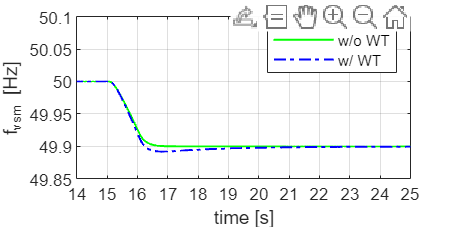

figure('Name','VSM'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on

plot(t_dc_link_big_wo,VSM_freq_big_wo+50,'g-',LineWidth=1);
plot(t_dc_link_big,VSM_freq_big+50,'b-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 25 49.85 50.1])
legend('w/o WT', 'w/ WT','Location','northeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('f_{vsm} [Hz]')
ay = gca;
ay.YTick = 49.5:0.05:50.5;
ay.XTick =0:1:25;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+ "vsm"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = pathName+"vsm"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

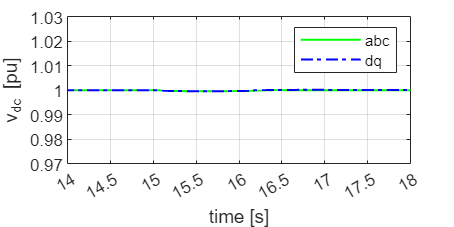

%% DC link
figure('Name','DClinkv'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on

plot(t_dc_link_big_wo,DC_voltage_big_wo,'g-',LineWidth=1);
plot(t_dc_link_big,DC_voltage_big,'b-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 18 0.97 1.03])
legend('abc', 'dq') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('v_{dc} [pu]')
ay = gca;
ay.YTick = 0.85:0.01:1.16;
ay.XTick =0:0.5:24;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+"DClinkv"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name =pathName+ "DClinkv"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## vsc voltage

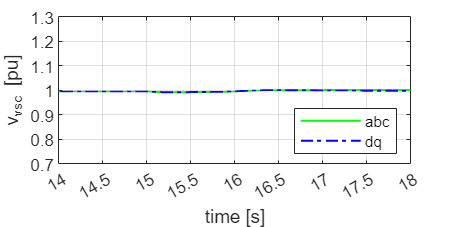


figure('Name','v_vsc'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on

plot(t_dc_link_big_wo,v_d_vsc_vec_big_wo,'g-',LineWidth=1);
plot(t_dc_link_big,v_d_vsc_vec_big,'    b-.',LineWidth=1);
% plot(t_vsm,v_q_vsc_vec,'r-',LineWidth=1);
% plot(t_dc_link_big,v_q_vsc_vec_big,'m-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 18 0.7 1.3])
legend('abc', 'dq','Location','southeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('v_{vsc} [pu]')
ay = gca;
ay.YTick = 0:0.1:5;
ay.XTick =0:0.5:25;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+"v_vsc"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = pathName+"v_vsc"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Grid Powers

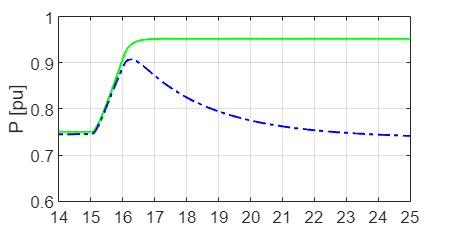


figure('Name','PQ_vsc'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
% grid on


box on
hold on
plot(t_dc_link_big_wo,P_vsc_big_wo,'g-',LineWidth=1);
plot(t_dc_link_big,P_vsc_big,'b-.',LineWidth=1);
ylabel('P [pu]')
axis([14 25 0.6 1])
ay = gca;
ay.YTick = 0:0.1:1;
ay.XTick =0:1:25;
grid on
hold off


set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+"PQ_vsc"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = pathName+"PQ_vsc"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Reactive

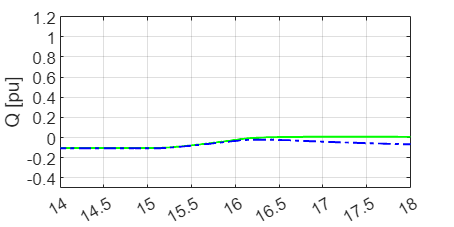

figure('Name','Q_vsc'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
% grid on


box on
hold on
plot(t_dc_link_big_wo,Q_vsc_big_wo,'g-',LineWidth=1);
plot(t_dc_link_big,Q_vsc_big,'b-.',LineWidth=1);
ylabel('Q [pu]')
axis([14 18 -0.5 1.2])
ay = gca;
ay.YTick = -1:0.2:2;
ay.XTick =0:0.5:24;
grid on
hold off


set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+"Q_vsc"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name = pathName+"Q_vsc"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Turbine

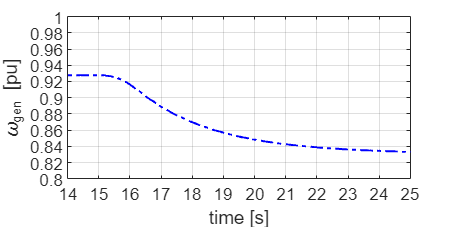


figure('Name','w_tur'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on


% plot(t_dc_link_big_wo,w_wt,'g-',LineWidth=1);
plot(t_dc_link_big,w_wt_big,'b-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 25 0.8 1])
% legend('abc', 'dq','Location','southeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('\omega_{gen} [pu]')
ay = gca;
ay.YTick = -1:0.02:5;
ay.XTick =0:1:30;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+ "w_tur"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name =pathName + "w_tur"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)

## Turbine

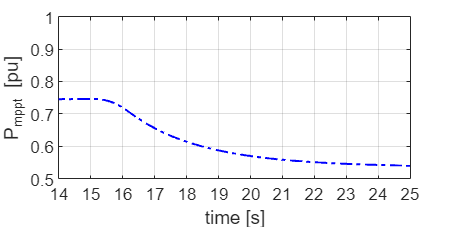


figure('Name','P_mppt'+ figName,'units', 'centimeters','Position',[0.1 0.1 8 4])
hold on
grid on
box on


% plot(t_dc_link_big_wo,w_wt,'g-',LineWidth=1);
plot(t_dc_link_big,P_mppt_big,'b-.',LineWidth=1);
% plot(t_RMSv,v_GFM,'r-',LineWidth=1);
% plot(t,v_LOAD,'m-',LineWidth=1);
% title(plotTitle,Interpreter="tex")

axis([14 25 0.5 1])
% legend('abc', 'dq','Location','southeast') %'Detailed WPP model onshore PoC','Aggregated WPP model onshore PoC','Location','NorthOutside') ;
xlabel('time [s]')
ylabel('P_mppt [pu]')
ay = gca;
ay.YTick = -1:0.1:5;
ay.XTick =0:1:30;

hold off

set(gcf,'paperunits','centimeters','Paperposition',[0 0 6.5 4])
plot_file_name = pathName+ "P_mppt"+ figName +".png";
exportgraphics(gcf,plot_file_name)
plot_file_name =pathName + "P_mppt"+ figName +".pdf";

exportgraphics(gcf,plot_file_name)